# Sistema Incierto

clear
clc

Kt = 0.31739;
Ke = 0.46839;
Ra = 6.8562;
B = 1.1278e-3;
J = 1.45e-3;

N = 48;

sysM = ss(tf(Ra,[Ra*J Ke*Kt+Ra*B 0]));
sysE = ss(tf(48*(Kt/Ra)));

## Planta Generalizada

M1 = 1.35;A1 = 0.001;Wb1 = 150;
M3 = 0.005;A3 = 2.5;Wb3 = 2*pi*140;

Wp      = 1*tf(1,1);
W1      = tf([1/M1 Wb1],[1 A1*Wb1]);
W2      = 0.075*tf(1,1);
%W2      =tf([1/M2 Wb2],[1 A2*Wb2]);
W3      = tf([1/M3 Wb3],[1 A3*Wb3]);
Wn      = 0.01;





systemnames     = 'sysM sysE Wp Wn W1 W2 W3';
inputvar        = '[ p; n ; r ; u]';
outputvar       = '[ W1; W2 ; W3;-sysM - Wn + r]';
input_to_sysM   = '[-Wp + sysE]';
input_to_sysE   = '[u]';
input_to_Wn     = '[n]';
input_to_W1     = '[-sysM - Wn + r]';
input_to_W2     = '[sysE]';
input_to_W3     = '[sysM]';
input_to_Wp     = '[p]';

sysnom_ic = sysic;

## Controlador

ncont = 1;
nmeas = 1;
[K1,sys_CL,gam1,info] = hinfsyn(sysnom_ic,nmeas,ncont);

## Lazo cerrado SIN filtros

display('Polos del controlador')

Polos del controlador


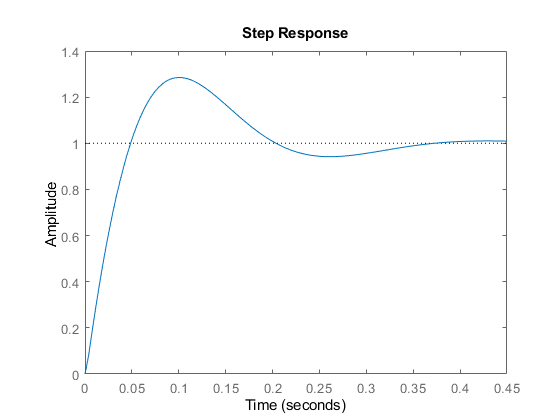

eig(K1);

sysnom = (sysE - Wp)*sysM;

L  = sysnom*K1; % funcion  de lazo directo

sysnom_CL = feedback(L,1);

figure (1)
step(sysnom_CL);

## Comprobacion W1

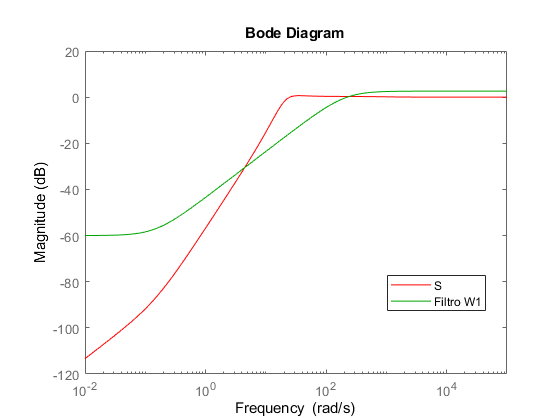

S = feedback(1,L);

figure (2)
bodemag(S,'r');
hold on
bodemag(1/W1,'g');
legend("S","Filtro W1","Location","best")

## Comprobacion W2

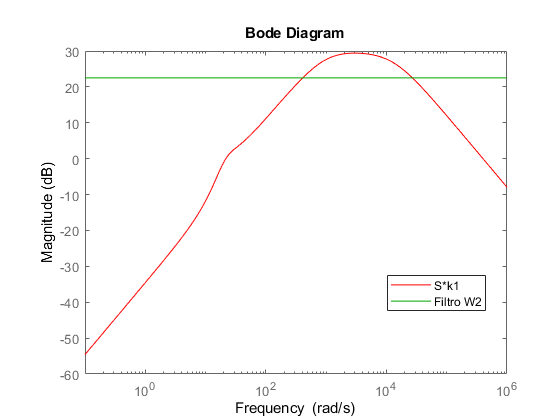

S = feedback(1,L);
figure(3)
bodemag(S*K1,'r');
hold on
bodemag(1/W2,'g');
legend("S*k1","Filtro W2","Location","best")

## Comprobacion W3

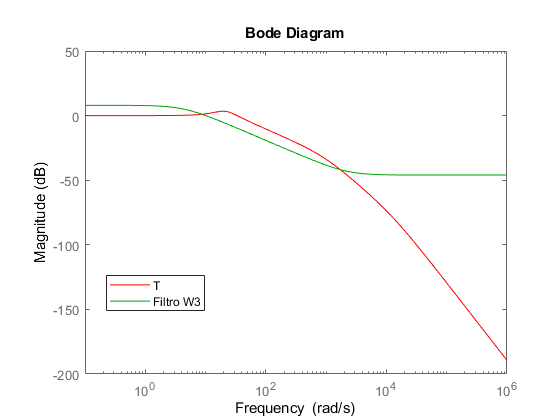

T = feedback(L,1);
figure (4)
bodemag(T,'r');
hold on
bodemag(1/W3,'g');
legend("T","Filtro W3","Location","best")

## Diferentes controladores

### Original

M1 = 1.35;A1 = 0.001;Wb1 = 15;

M3 = 0.007;A3 = 2.5;Wb3 = 2*pi*140;

W1      = tf([1/M1 Wb1],[1 A1*Wb1])

W2      = 0.05*tf(1,1)

W3      = tf([1/M3 Wb3],[1 A3*Wb3])

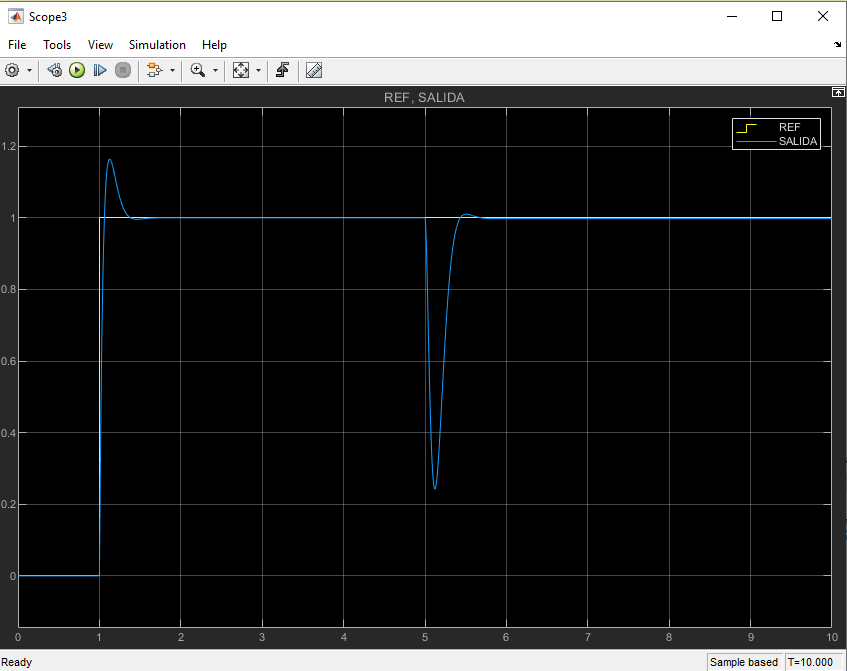

### Cambios C1

#### Cambios M1

**M1 = 1.35;A1 = 0.001;Wb1 = 15; (original)**

M1 = 2;A1 = 0.001;Wb1 = 15;

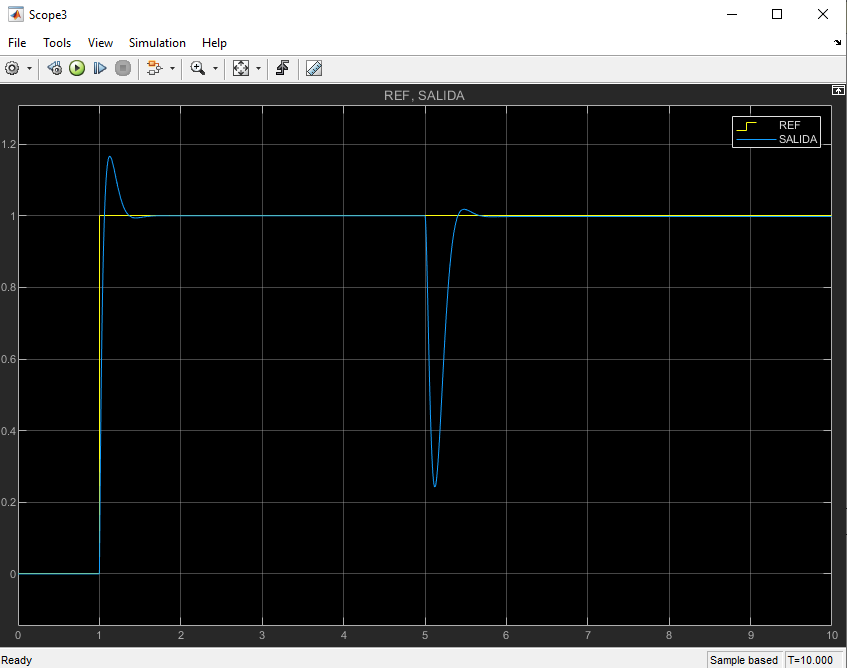

M1 = 10;A1 = 0.001;Wb1 = 15;

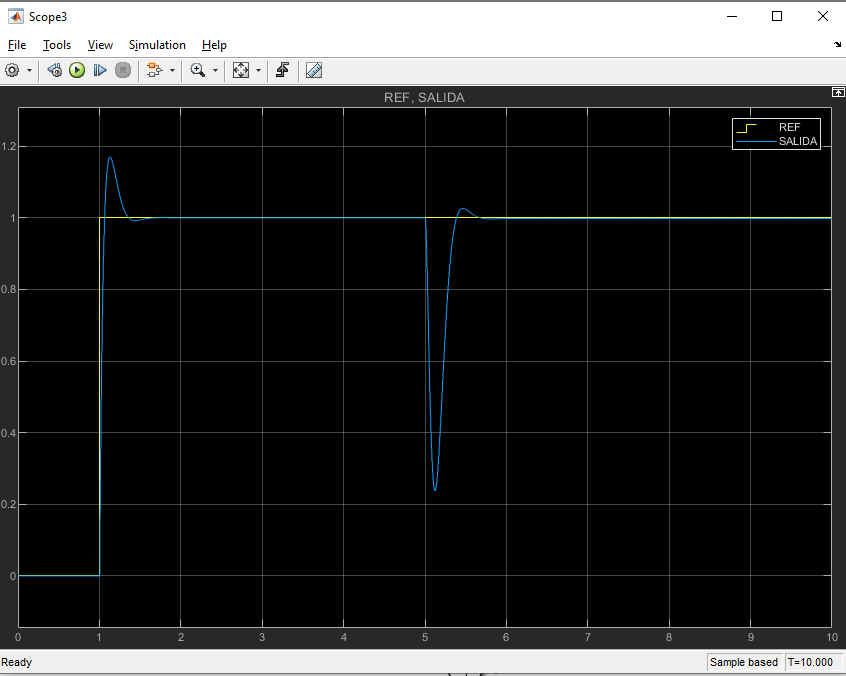

#### Cambios A1

**M1 = 1.35;A1 = 0.001;Wb1 = 15; (original)**

M1 = 1.35;A1 = 0.01;Wb1 = 15;

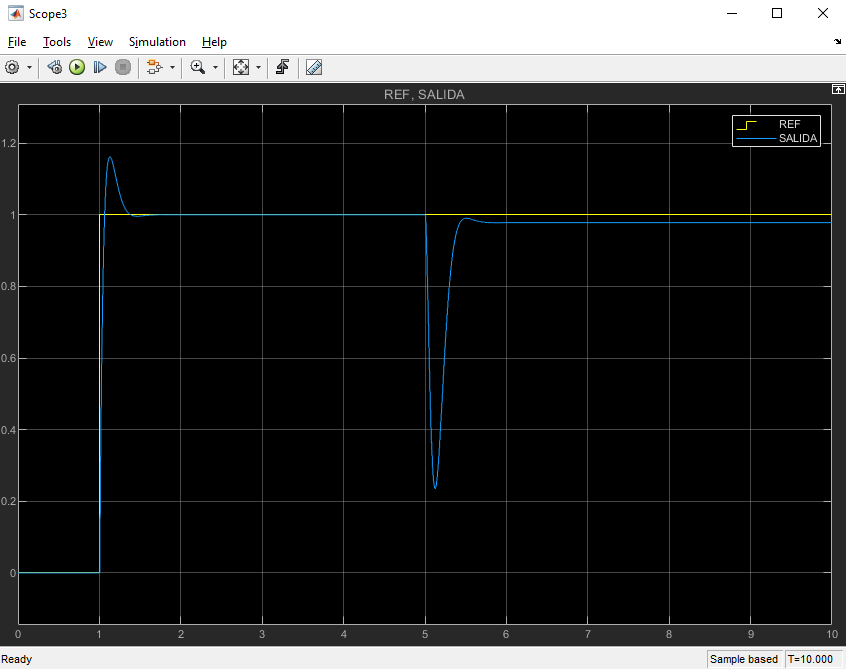

M1 = 1.35;A1 = 0.1;Wb1 = 15;

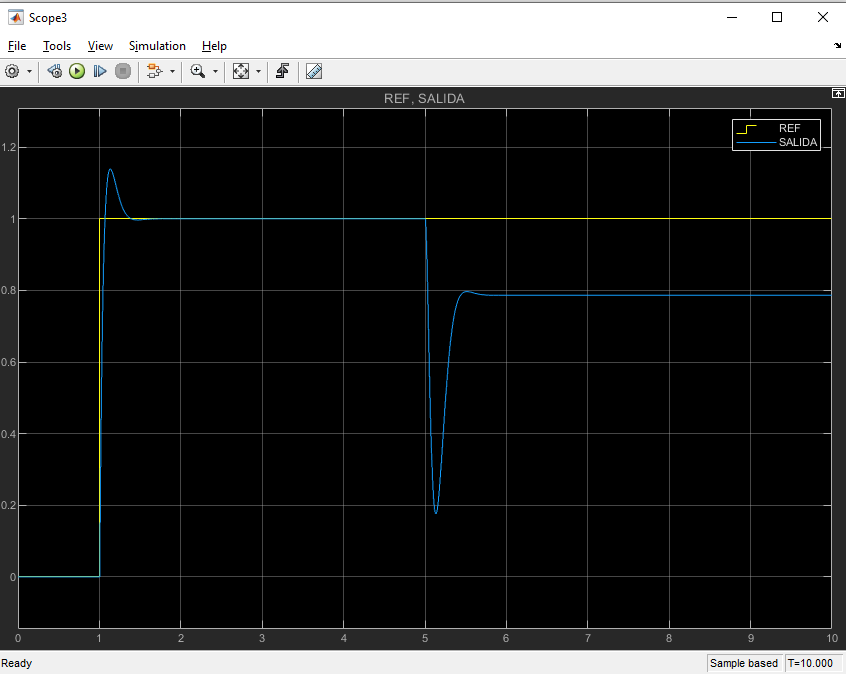

M1 = 1.35;A1 = 1;Wb1 = 15;

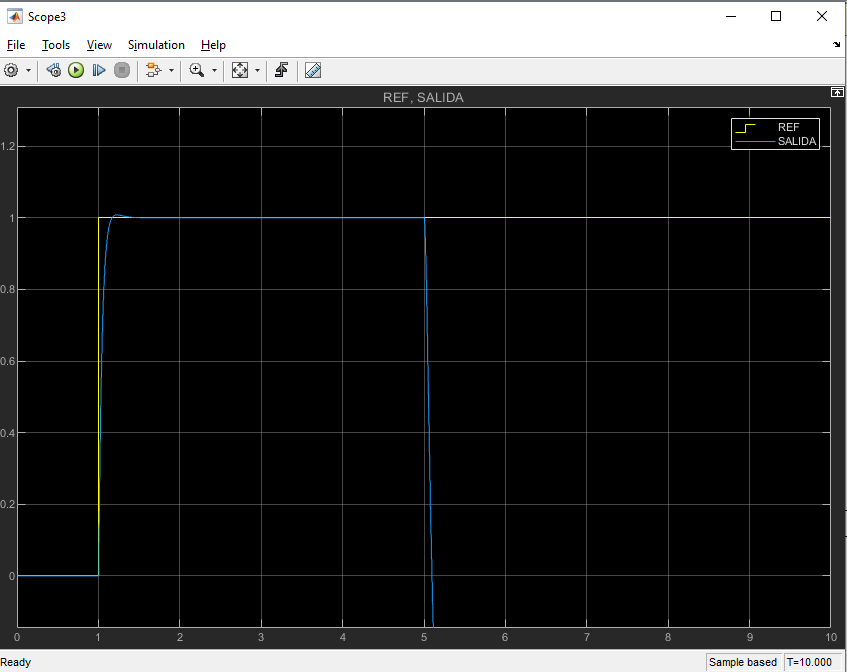

#### Cambios Wb1

M1 = 1.35;A1 = 0.001;Wb1 = 1.5;

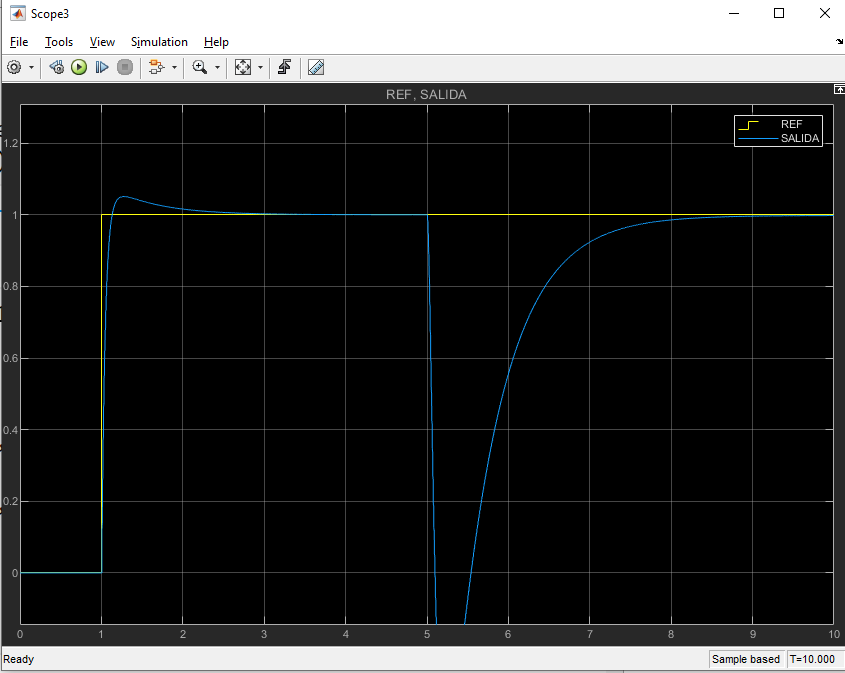

**M1 = 1.35;A1 = 0.001;Wb1 = 15; (original)**

M1 = 1.35;A1 = 0.001;Wb1 = 30;

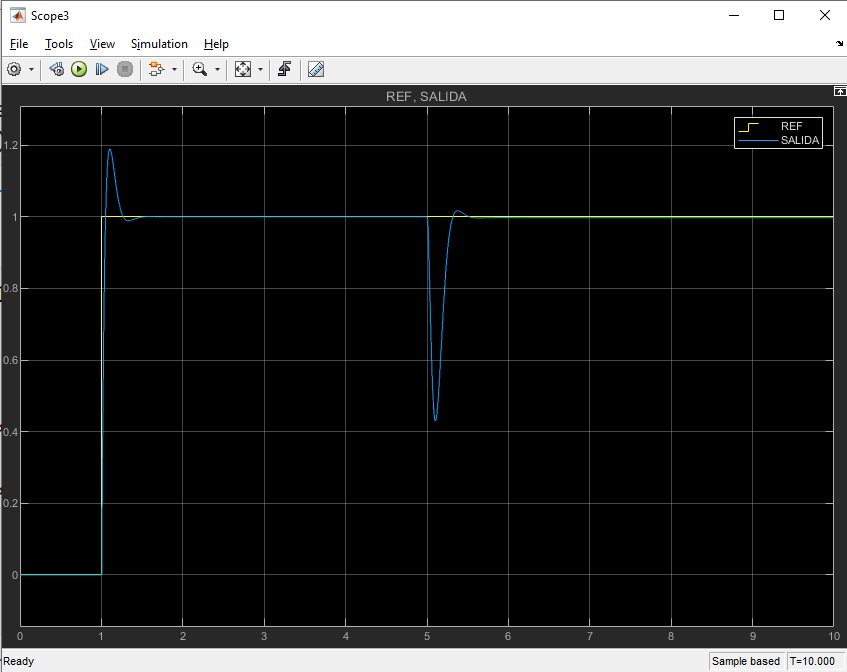

M1 = 1.35;A1 = 0.001;Wb1 = 100;

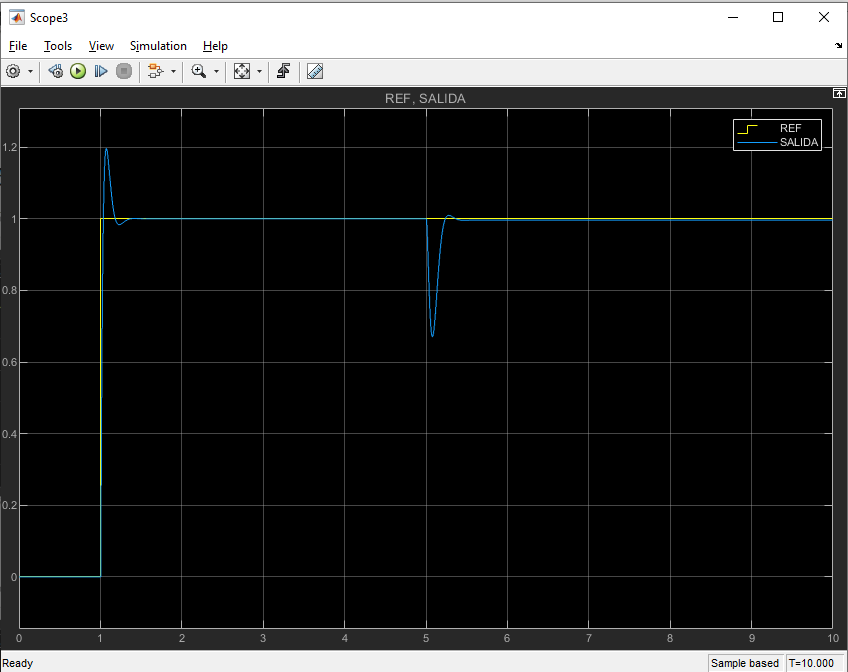

M1 = 1.35;A1 = 0.001;Wb1 = 1000;

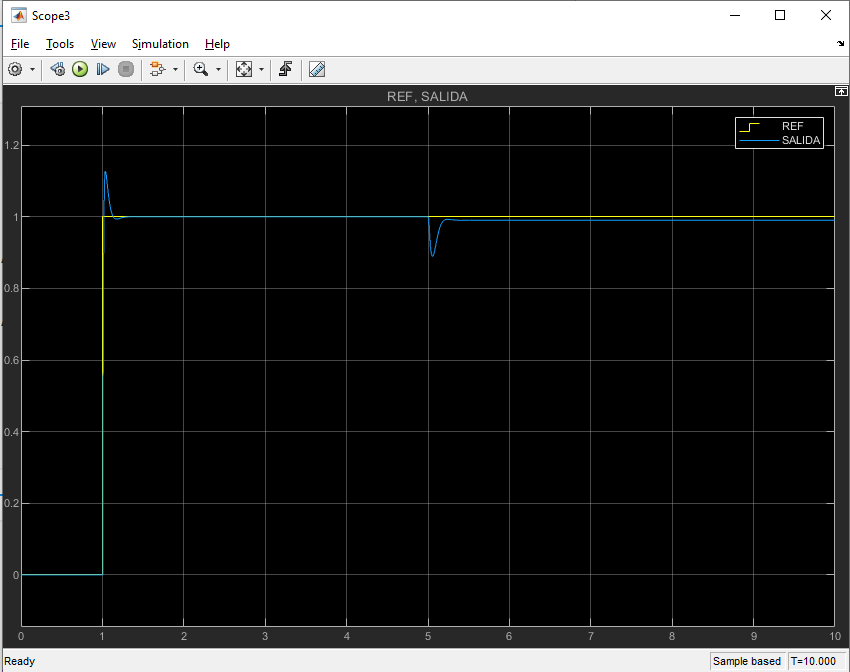

## Calculo del controlador digital

Kd = c2d(K1,0.0001);

display('Matrices Controlador Discreto')

Matrices Controlador Discreto


for i = 1:4
    for j = 1:4
        display(['A[' num2str(i-1) '][' num2str(j-1) '] = ' num2str(Kd.a(i,j)) ';'])
    end
end

A[0][0] = 0.91596;
A[0][1] = -34.6933;
A[0][2] = 1.2106;
A[0][3] = 4.1432;
A[1][0] = -0.00036299;
A[1][1] = 0.33021;
A[1][2] = 0.053701;
A[1][3] = -0.009865;
A[2][0] = -6.5411e-18;
A[2][1] = -9.5224e-15;
A[2][2] = 0.99999;
A[2][3] = -1.4377e-16;
A[3][0] = -0.0022395;
A[3][1] = -2.3436;
A[3][2] = 0.26771;
A[3][3] = 0.75235;



for j = 1:4
    
    display(['B[' num2str(j-1) '][' num2str(0) '] = ' num2str(Kd.b(j,1)) ';'])
end

B[0][0] = -0.10239;
B[1][0] = -0.015013;
B[2][0] = 0.0016;
B[3][0] = -0.074898;



for i = 1:4

    display(['C[0][' num2str(i-1) '] = ' num2str(Kd.c(i)) ';'])
end

C[0][0] = -11.4043;
C[0][1] = -4773.3939;
C[0][2] = 123.5144;
C[0][3] = 689.2054;
